clearvars;
% create the computational grid
Nx = 128;           % number of grid points in the x (row) direction
Ny = 128;           % number of grid points in the y (column) direction
dx = 0.1e-3;        % grid point spacing in the x direction [m]
dy = 0.1e-3;        % grid point spacing in the y direction [m]
kgrid = kWaveGrid(Nx, dx, Ny, dy);

% define the properties of the propagation medium   
medium.alpha_coeff = 0.75;  % [dB/(MHz^y cm)]
medium.alpha_power = 1.5;
medium.sound_speed = 1500 * ones(Nx, Ny);   % [m/s]
medium.sound_speed(1:Nx/2, :) = 5100;       % [m/s]
medium.density = 1000 * ones(Nx, Ny);       % [kg/m^3]
medium.density(1:Nx/2, :) = 2710;          % [kg/m^3]
kgrid.makeTime(medium.sound_speed);
% define a single source point
source.p_mask = zeros(Nx, Ny);
source.p_mask(Nx/2, Ny/2) = 1;

% define a time varying sinusoidal source
source_freq = 0.25e6;   % [Hz]
source_mag = 10;         % [Pa]
source.p = source_mag * sin(2 * pi * source_freq * kgrid.t_array);

% filter the source to remove high frequencies not supported by the grid
source.p = filterTimeSeries(kgrid, medium, source.p);

Filtering input signal...
  maximum frequency supported by kgrid: 7.5MHz (2 PPW)
  filter cutoff frequency: 5MHz (3 PPW)
  computation complete.


Running k-Wave simulation...
  start time: 10-Mar-2023 12:58:19
  reference sound speed: 5100m/s
  dt: 5.8824ns, t_end: 12.0647us, time steps: 2052
  input grid size: 128 by 128 grid points (12.8 by 12.8mm)
  maximum supported frequency: 7.5MHz


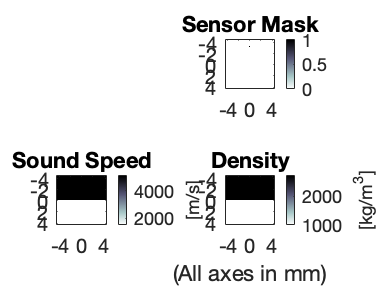

  precomputation completed in 1.8548s
  starting time loop...
  estimated simulation time 27.6561s...


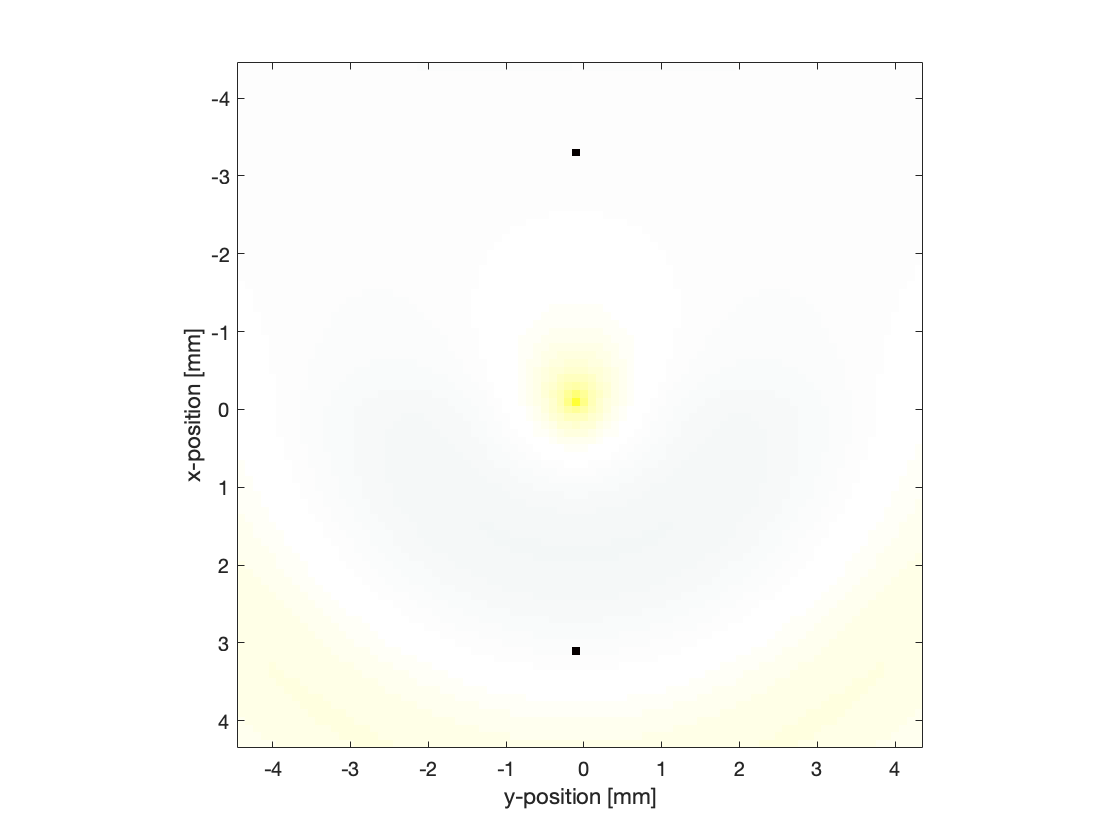

  simulation completed in 21.8356s
  total computation time 23.8885s



% define a two sensor points
sensor.mask = zeros(Nx, Ny);
sensor.mask(Nx/4, Ny/2) = 1;
sensor.mask(end - Nx/4,Ny/2) = 1;

% run the simulation
sensor_data = kspaceFirstOrder2D(kgrid, medium, source, sensor, ...
    'PlotLayout', true, 'PlotPML', false);

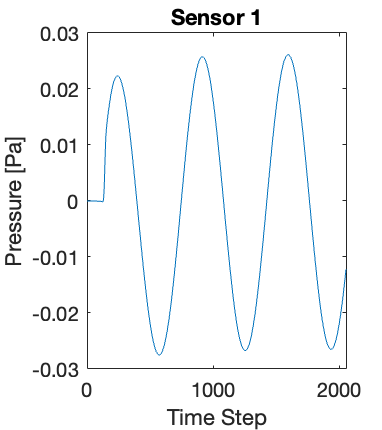


% =========================================================================
% VISUALISATION
% =========================================================================
[t, t_sc, t_prefix] = scaleSI(kgrid.t_array(end));
% plot a trace from the simulated sensor data
figure;
plot(sensor_data(1, :));
xlabel('Time Step');
ylabel('Pressure [Pa]');
title("Sensor 1")
scaleFig(1, 1.5);

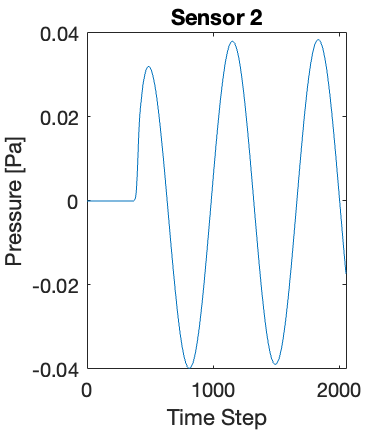


figure;
plot(sensor_data(2, :));
xlabel('Time Step');
ylabel('Pressure [Pa]');
title("Sensor 2")
scaleFig(1, 1.5);